syms y t
format long
f=@(y,t) y*exp(t)

f = function_handle with value:
    @(y,t)y*exp(t)


n=10

n =     10


h=0.1

h =    0.100000000000000


t0=1

t0 =      1


y0=0.1

y0 =    0.100000000000000


t=[1,n]

t =      1    10


y=[1,n]

y =      1    10


t(1)=1

t =      1    10


y(1)=0.1

y =    0.100000000000000  10.000000000000000


for i=1:n
    y(i+1)=y(i)+h*f(t(i),y(i));
    t(i+1)=t(i)+h;
    disp([i,t(i+1),y(i+1)])
end

   1.000000000000000   1.100000000000000   0.210517091807565

   2.000000000000000   1.200000000000000   0.346291868278525

   3.000000000000000   1.300000000000000   0.515949692688169

   4.000000000000000   1.400000000000000   0.733729423561438

   5.000000000000000   1.500000000000000   1.025326171083745

   6.000000000000000   1.600000000000001   1.443526872901497

   7.000000000000000   1.700000000000001   2.121224145837614

   8.000000000000000   1.800000000000001   3.539252329996153

   9.000000000000000   1.900000000000001   9.738660939292746

   1.0e+03 *

   0.010000000000000   0.002000000000000   3.232293436356928



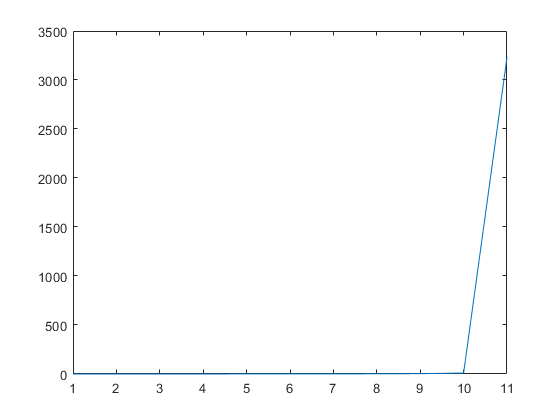

plot(y)
hold off

syms y(t)
edo1=diff(y(t),t)==y.*exp(t)

$$edo1(t) = \frac{\partial }{\partial t}y\left(t\right)={\mathrm{e}}^{t}\,y\left(t\right)$$

a=dsolve(edo1,y(1)==0.1)

$$a = \frac{{\mathrm{e}}^{-\mathrm{e}}\,{\mathrm{e}}^{{\mathrm{e}}^{t}}}{10}$$

syms y t
format long
f=@(y,t) y*exp(t)

f = function_handle with value:
    @(y,t)y*exp(t)


n=10

n =     10


h=0.1

h =    0.100000000000000


t0=1

t0 =      1


y0=0.1

y0 =    0.100000000000000


t=[1,n]

t =      1    10


y=[1,n]

y =      1    10


t(1)=1

t =      1    10


y(1)=0.1

y =    0.100000000000000  10.000000000000000


phi=@(t) (exp(-exp(1.0)).*exp(exp(t))).*1/10

phi = function_handle with value:
    @(t)(exp(-exp(1.0)).*exp(exp(t))).*1/10


disp('i t[i] y[i] phi(t[i]) erro')

i t[i] y[i] phi(t[i]) erro


for i=1:n
    y(i+1)=y(i)+h*f(t(i),y(i));
    t(i+1)=t(i)+h;
    erro=abs(y(i+1)-phi(t(i+1)));
    disp([i,t(i+1),y(i+1),phi(t(i+1)),erro])
end

   1.000000000000000   1.100000000000000   0.210517091807565   0.133093831766436   0.077423260041129

   2.000000000000000   1.200000000000000   0.346291868278525   0.182546563010884   0.163745305267640

   3.000000000000000   1.300000000000000   0.515949692688169   0.258833507069484   0.257116185618685

   4.000000000000000   1.400000000000000   0.733729423561438   0.380729185955790   0.353000237605648

   5.000000000000000   1.500000000000000   1.025326171083745   0.583227555202046   0.442098615881700

   6.000000000000000   1.600000000000001   1.443526872901497   0.934415109230184   0.509111763671313

   7.000000000000000   1.700000000000001   2.121224145837614   1.573150773294817   0.548073372542797

   8.000000000000000   1.800000000000001   3.539252329996153   2.797652137098878   0.741600192897275

   9.000000000000000   1.900000000000001   9.738660939292746   5.285818717857224   4.452842221435522

   1.0e+03 *

   0.010000000000000   0.002000000000000   3.232293436356928   0.010

phi=@(t) (exp(-exp(1.0)).*exp(exp(t))).*1/10

phi = function_handle with value:
    @(t)(exp(-exp(1.0)).*exp(exp(t))).*1/10


erro_absoluto=abs(y(11)-phi(2.0))

erro_absoluto =      3.221615397623485e+03


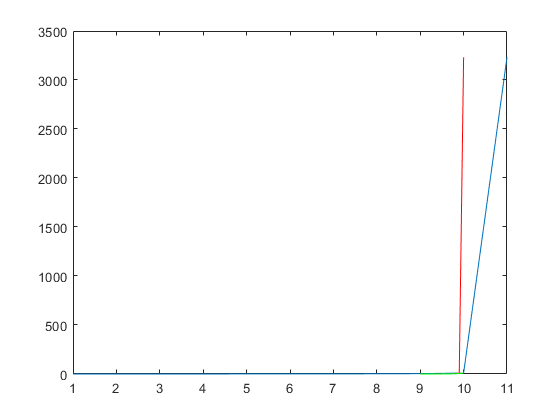

hold on
plot(9:0.1:10,y,'color',[1.0,0.0,0.0])
plot(9:0.1:10,phi(t),'Color',[0.0,1.0,0.0])
hold off

clear all
syms Y(t)
[t,y]=meshgrid(-5:0.5:5,-5:0.5:5);
f=@(t,y) y.*exp(t);
u=ones(length(t));
v=f(t,y);
l=sqrt(1+v.^2)

l = 	1.0e+02 *

   0.010005673381857   0.010015414345409   0.010041845277127   0.010113342914877   0.010305187064856   0.010809480445318   0.012074315600556   0.014982245189546   0.020936528081120   0.031932719942539   0.050990195135928   0.083040379160669   0.136281474336487   0.224307472697566   0.369588115451323   0.609206777503699   1.004326631993715   1.655802795042679   2.729925817234659   4.500867674008919   7.420664693072771
   0.010004595686872   0.010012487445849   0.010033908103102   0.010091905715981   0.010247900914712   0.010660410061210   0.011708508391323   0.014171055480977   0.019340474362180   0.029068124610511   0.046097722286464   0.074863346856987   0.122730756537775   0.201923778365637   0.332657863002090   0.548303426200054   0.903904478815538   1.490228890411680   2.456937102117085   4.050783251834162   6.678599646219528
   0.010003631335051   0.010009867915539   0.010026801095297   0.010072686391668   0.010196372074550   0.010525241811880   0.011371236617975  

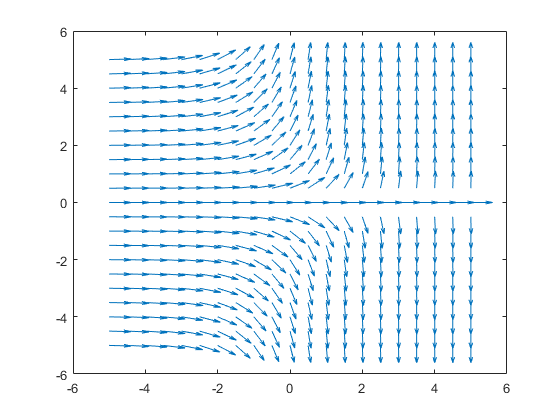

quiver(t,y,u./l,v./l)
hold off

syms y t
format long
f=@(y,t) y*exp(t)

f = function_handle with value:
    @(y,t)y*exp(t)


n=100

n =    100


h=0.01

h =    0.010000000000000


t0=1

t0 =      1


y0=0.1

y0 =    0.100000000000000


t=[1,n]

t =      1   100


y=[1,n]

y =      1   100


t(1)=1

t =      1   100


y(1)=0.1

y = 	1.0e+02 *

   0.001000000000000   1.000000000000000


for i=1:n
    y(i+1)=y(i)+h*f(t(i),y(i));
    t(i+1)=t(i)+h;
    disp([i,t(i+1),y(i+1)])
end

   1.000000000000000   1.010000000000000   0.111051709180756

   2.000000000000000   1.020000000000000   0.122337981328784

   3.000000000000000   1.030000000000000   0.133865368550274

   4.000000000000000   1.040000000000000   0.145640729152022

   5.000000000000000   1.050000000000000   0.157671246517059

   6.000000000000000   1.060000000000000   0.169964449463814

   7.000000000000000   1.070000000000000   0.182528234230586

   8.000000000000000   1.080000000000000   0.195370888243125

   9.000000000000000   1.090000000000000   0.208501115841287

  10.000000000000000   1.100000000000000   0.221928066161288

  11.000000000000000   1.110000000000000   0.235661363393475

  12.000000000000000   1.120000000000000   0.249711139662101

  13.000000000000000   1.130000000000000   0.264088070803951

  14.000000000000000   1.140000000000000   0.278803415357308

  15.000000000000000   1.150000000000000   0.293869057112491

  16.000000000000000   1.160000000000000   0.309297551620765

  17.000

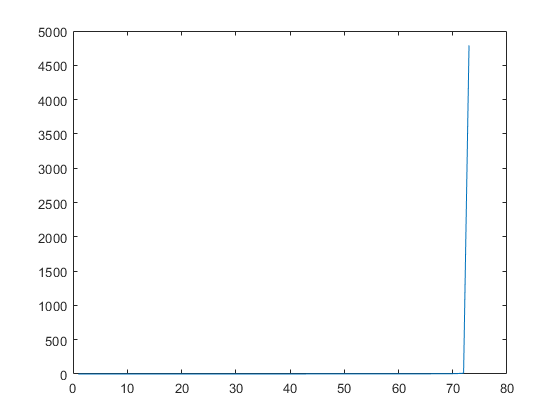

plot(y)
hold off

syms y(t)
edo1=diff(y(t),t)==y.*exp(t)

$$edo1(t) = \frac{\partial }{\partial t}y\left(t\right)={\mathrm{e}}^{t}\,y\left(t\right)$$

a=dsolve(edo1,y(1)==0.1)

$$a = \frac{{\mathrm{e}}^{-\mathrm{e}}\,{\mathrm{e}}^{{\mathrm{e}}^{t}}}{10}$$

syms y t
format long
f=@(y,t) y*exp(t)

f = function_handle with value:
    @(y,t)y*exp(t)


n=100

n =    100


h=0.01

h =    0.010000000000000


t0=1

t0 =      1


y0=0.1

y0 =    0.100000000000000


t=[1,n]

t =      1   100


y=[1,n]

y =      1   100


t(1)=1

t =      1   100


y(1)=0.1

y = 	1.0e+02 *

   0.001000000000000   1.000000000000000


phi=@(t) (exp(-exp(1.0)).*exp(exp(t))).*1/10

phi = function_handle with value:
    @(t)(exp(-exp(1.0)).*exp(exp(t))).*1/10


disp('i t[i] y[i] phi(t[i]) erro')

i t[i] y[i] phi(t[i]) erro


for i=1:n
    y(i+1)=y(i)+h*f(t(i),y(i));
    t(i+1)=t(i)+h;
    erro=abs(y(i+1)-phi(t(i+1)));
    disp([i,t(i+1),y(i+1),phi(t(i+1)),erro])
end

   1.000000000000000   1.010000000000000   0.111051709180756   0.102769577709584   0.008282131471173

   2.000000000000000   1.020000000000000   0.122337981328784   0.105644863150499   0.016693118178286

   3.000000000000000   1.030000000000000   0.133865368550274   0.108630714764121   0.025234653786153

   4.000000000000000   1.040000000000000   0.145640729152022   0.111732248624783   0.033908480527240

   5.000000000000000   1.050000000000000   0.157671246517059   0.114954853795302   0.042716392721758

   6.000000000000000   1.060000000000000   0.169964449463814   0.118304208693501   0.051660240770313

   7.000000000000000   1.070000000000000   0.182528234230586   0.121786298542350   0.060741935688235

   8.000000000000000   1.080000000000000   0.195370888243125   0.125407433981969   0.069963454261155

   9.000000000000000   1.090000000000000   0.208501115841287   0.129174270927877   0.079326844913410

  10.000000000000000   1.100000000000000   0.221928066161288   0.133093831766436  

phi=@(t) (exp(-exp(1.0)).*exp(exp(t))).*1/10

phi = function_handle with value:
    @(t)(exp(-exp(1.0)).*exp(exp(t))).*1/10


erro_absoluto=abs(y(101)-phi(2.0))

erro_absoluto =    Inf


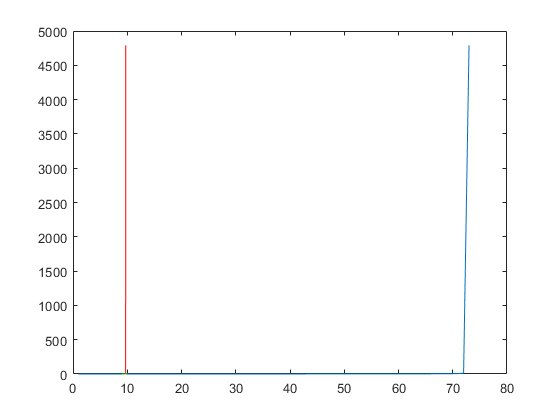

hold on
plot(9:0.01:10,y,'color',[1.0,0.0,0.0])
plot(9:0.01:10,phi(t),'Color',[0.0,1.0,0.0])
hold off

clear all
syms Y(t)
[t,y]=meshgrid(-5:0.5:5,-5:0.5:5);
f=@(t,y) y.*exp(t);
u=ones(length(t));
v=f(t,y);
l=sqrt(1+v.^2)

l = 	1.0e+02 *

   0.010005673381857   0.010015414345409   0.010041845277127   0.010113342914877   0.010305187064856   0.010809480445318   0.012074315600556   0.014982245189546   0.020936528081120   0.031932719942539   0.050990195135928   0.083040379160669   0.136281474336487   0.224307472697566   0.369588115451323   0.609206777503699   1.004326631993715   1.655802795042679   2.729925817234659   4.500867674008919   7.420664693072771
   0.010004595686872   0.010012487445849   0.010033908103102   0.010091905715981   0.010247900914712   0.010660410061210   0.011708508391323   0.014171055480977   0.019340474362180   0.029068124610511   0.046097722286464   0.074863346856987   0.122730756537775   0.201923778365637   0.332657863002090   0.548303426200054   0.903904478815538   1.490228890411680   2.456937102117085   4.050783251834162   6.678599646219528
   0.010003631335051   0.010009867915539   0.010026801095297   0.010072686391668   0.010196372074550   0.010525241811880   0.011371236617975  

quiver(t,y,u./l,v./l)